n = 4;
A = rand(n);
A = make_density_operator(A);

disp("A's eigenvalue:");

A's eigenvalue:


disp(eig(A));

    0.0861
    0.1098
    0.2031
    0.6010




fprintf("S(A) = %d\n", q_entropy(A));

S(A) = 1.563157e+00



fprintf("Cr(A) = %d\n", relative_entropy_coherence(A));

Cr(A) = 4.209318e-01



D = diag(diag(A))

D =     0.2198         0         0         0
         0    0.3152         0         0
         0         0    0.2298         0
         0         0         0    0.2352


fprintf("Cr(D) = %d\n", relative_entropy_coherence(D));

Cr(D) = 0


rho = rand(n);
rho = make_density_operator(rho);

sigma = rand(n);
sigma = make_density_operator(sigma);

tol = 1e-2;

[val, ~] = hypothesis_testing_relative_entropy(rho, rho, tol)

 
Calling SDPT3 4.0: 33 variables, 16 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 16
 dim. of sdp    var  = 16,   num. of sdp  blk  =  2
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.2e+00|1.6e+01|1.7e+03| 3.261044e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.965|3.6e-07|6.4e-01|1.0e+02| 3.491283e+01 -8.498503e-01| 0:0:00| chol  1  1 
 2|1.000|0.776|5.9e-07|1.5e-01|2.5e+01| 1.455514e+01 -6.524928e-01| 0:0:00| chol  1  1 
 3|0.949|0.775|7.3e-07|3.5e-02|5.2e+0

val = 0.0145

% max-relative entropy

n = 5;

rho = rand(n);
rho = make_density_operator(rho);

sigma = rand(n);
sigma = make_density_operator(sigma);

% sigma = [1 0; 0 0];

d = max_relative_entropy(rho, sigma);

cvx_begin sdp 
    variable l;
    minimize l;
    subject to
        rho <= l * sigma;
cvx_end;

 
Calling SDPT3 4.0: 15 variables, 1 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  1
 dim. of sdp    var  =  5,   num. of sdp  blk  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|7.0e+00|1.7e+01|5.0e+02|-2.885707e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.851|0.973|1.0e+00|5.7e-01|6.8e+01|-1.342081e+00 -2.593918e+01| 0:0:00| chol  1  1 
 2|1.000|0.843|3.9e-16|9.8e-02|1.3e+01|-1.524312e+00 -1.313193e+01| 0:0:00| chol  1  1 
 3|0.170|1.000|8.5e-15|1.0e-03|4.3e+01|-2.651829e+01 -6.920238e+


disp(d);

    4.9817



disp(log2(cvx_optval));

    4.9817



% positive projection

n = 4;
A = zeros(n);
for i = 1:3
    v = rand(n, 1);
    A = A + v * v';
end
A = 0.5 * (A + A');

disp(A);

    1.5695    0.5591    1.1475    1.3937
    0.5591    0.5214    0.5100    0.5769
    1.1475    0.5100    1.0762    1.2969
    1.3937    0.5769    1.2969    1.5685




tol = 1e-5;

positive_projection(A, tol);



$$C_{\max } \left(\rho \right):=\inf_{\delta \in \mathcal{I}} \;D_{\max } \left(\rho \;||\;\delta \right)$$


% max-relative entropy of coherence

n = 4;
rho = make_density_operator(rand(n));

cmax = coherence_max_relative_entropy(rho)

 
Calling SDPT3 4.0: 18 variables, 5 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  5
 dim. of sdp    var  =  6,   num. of sdp  blk  =  2
 dim. of linear var  =  5
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|6.7e+00|1.1e+01|1.1e+03| 2.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.915|1.7e-06|1.0e+00|1.2e+02| 1.965006e+01 -7.793532e+00| 0:0:00| chol  1  1 
 2|1.000|0.924|1.9e-06|8.7e-02|1.9e+01| 1.121192e+01 -2.117185e+00| 0:0:00| chol  1  1 
 3|0.726|1.000|6.1e-07|1.0e-03|6.0e+00

cmax = 1.3064


$$\begin{array}{l}
C_{\max }^{\epsilon } \left(\rho \right):=\min \left\lbrace C_{\max } \left(\rho^{\prime } \right)\;|\;F\left(\rho ,\rho^{\prime } \right)\ge 1-\epsilon \right\rbrace \\
C_{\max }^{\epsilon } \left(\phi \right)=\log_2 \;\min \;\lambda \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;s\ldotp t\ldotp \;F\left(\phi ,\rho \right)\ge 1-\epsilon \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\delta \in \mathcal{I}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\rho \le \lambda \;\delta \\
\;\;=\log_2 \;\min \;\lambda \\
\;\;\;\;s\ldotp t\ldotp \;F\left(\phi ,\rho \right)=1-\epsilon \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\delta \in \mathcal{I}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\rho \le \lambda \;\delta \\
\;\;=\log_2 \;\min \;\;\textrm{tr}\;D\\
\;\;\;\;s\ldotp t\ldotp \textrm{tr}\;\left(\phi \;\rho \right)=1-\epsilon \\
\;\;\;\;\;\;\;\;\;\;\;\Delta \left(D\right)=D\\
\;\;\;\;\;\;\;\;\;\;\;D\ge 0\\
\;\;\;\;\;\;\;\;\;\;\;\rho \le D
\end{array}$$


% smoothed coherence max relative entropy pure

d = 8;
% random v
v = randn(d, 1);

phi = v / norm(v);
Phi = phi * phi'

Phi =     0.0520    0.0223   -0.1007   -0.1770    0.0335   -0.0554    0.0403   -0.0388
    0.0223    0.0096   -0.0432   -0.0759    0.0144   -0.0238    0.0173   -0.0166
   -0.1007   -0.0432    0.1949    0.3428   -0.0648    0.1073   -0.0780    0.0752
   -0.1770   -0.0759    0.3428    0.6027   -0.1140    0.1887   -0.1372    0.1322
    0.0335    0.0144   -0.0648   -0.1140    0.0216   -0.0357    0.0259   -0.0250
   -0.0554   -0.0238    0.1073    0.1887   -0.0357    0.0591   -0.0429    0.0414
    0.0403    0.0173   -0.0780   -0.1372    0.0259   -0.0429    0.0312   -0.0301
   -0.0388   -0.0166    0.0752    0.1322   -0.0250    0.0414   -0.0301    0.0290



tol = 0.01;

coherence_max_relative_entropy(Phi)

ans = 2.3786

smoothed_coherence_max_relative_entropy_pure(Phi, tol)

ans = 2.1431


$$C_{\max ,\Delta } \left(\rho \right):=D_{\max } \left(\rho \;||\;\Delta \left(\rho \right)\right)\;\ge C_{\max } \left(\rho \right)$$


% coherence max delta relative entropy
n = 8;

% mixed states
% rho = make_density_operator(randn(n) + i * randn(n));

% pure states
v = rand(n, 1);
v(1) = 0;
v(2) = 0;
v(3) = 0;
v(4) = 0;
phi = v / norm(v);
rho = phi * phi';

cmax = coherence_max_relative_entropy(rho)

cmax = 1.7307

cmaxd = max_relative_entropy(rho, diag(diag(rho)))

cmaxd = 2.0000

cmaxdd = coherence_max_delta_relative_entropy(rho)

cmaxdd = 2.0000


$$\begin{array}{l}
C_{\max ,\Delta } \left(\phi \right)=C_0 \left(\phi \right)\\
=\log_2 \;\textrm{rank}\;\left\lbrack \Delta \left(\phi \right)\right\rbrack 
\end{array}$$


% coherence max delta relative entropy pure

n = 8;

% pure states
v = rand(n, 1);
v(1) = 0;
v(2) = 0;
v(3) = 0;
v(4) = 0;
phi = v / norm(v);
Phi = phi * phi';

coherence_max_delta_relative_entropy_pure(Phi)

ans = 2


$$\begin{array}{l}
C_{\max ,\Delta }^{\epsilon } \left(\rho \right):=\min \;\left\lbrace C_{\max ,\Delta } \left(\rho^{\prime } \right):F\left(\rho ,\rho^{\prime } \right)\ge 1-\epsilon \right\rbrace \\
C_{\max ,\Delta }^{\epsilon } \left(\phi \right)=\inf \;\log_2 \;\lambda \\
s\ldotp t\ldotp \;\;\textrm{tr}\;\phi \rho \ge 1-\epsilon \\
\;\;\;\;\;\;\;\;\;\;0\le \rho \le \lambda \;\Delta \left(\rho \right)\\
\;\;\;\;\;\;\;\;\;\;\textrm{tr}\;\rho =1
\end{array}$$


% smoothed coherence max delta relative entropy pure

d = 8;

% random v
v = randn(d, 1);
v(1) = 0;
v(2) = 0;
phi = v / norm(v);
Phi = phi * phi';

tol = 0.01;
bisection_tol = 0.001;

ecmaxd = smoothed_coherence_max_delta_relative_entropy_pure_bisection(Phi, tol, bisection_tol)

ecmaxd = 2.2589

cmaxd = coherence_max_delta_relative_entropy(Phi)

cmaxd = 2.5850

cmaxd_p = coherence_max_delta_relative_entropy_pure(Phi)

cmaxd_p = 2.5850


$$\begin{array}{l}
F_{\mathcal{O}} \left(\rho \;,m\right):=\max_{\Lambda \in \mathcal{O}} \;\textrm{tr}\;\left\lbrack \Lambda \left(\rho \right)\;\Psi_m \right\rbrack \\
\textrm{If}\;\mathcal{O}\in \left\lbrace \textrm{MIO},\textrm{DIO}\right\rbrace ,\textrm{then}\;\\
F_{\mathcal{O}} \left(\rho ,m\right)=\max \;\textrm{tr}\left(G\rho \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;s\ldotp t\ldotp 0\le G\le I,\Delta \left(G\right)=\frac{I}{m}
\end{array}$$


% coherence distillation one-shot rate

n = 16;

% rho = make_density_operator(randn(n) + i * randn(n));
rho = ones(n, 1) * ones(1, n) / n;
tol = 0.1;

Cd = coherence_distillation_oneshot_MIO_DIO(rho, tol)

 
Calling SDPT3 4.0: 514 variables, 241 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 241
 dim. of sdp    var  = 64,   num. of sdp  blk  =  2
 dim. of linear var  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.2e+01|2.0e+01|1.1e+04| 2.784728e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.959|2.3e-06|9.0e-01|7.3e+02| 2.607468e+02  4.106268e-01| 0:0:00| chol  1  1 
 2|1.000|0.988|1.9e-06|2.0e-02|1.1e+02| 1.078809e+02  4.740225e-01| 0:0:00| chol  1  1 
 3|0.987|1.000|1.2e-07|1.0e-03|1.6

Cd = 4.0875


$$\begin{array}{l}
\sqrt{F}\left(\rho ,\sigma \right)={\left\|\sqrt{\rho }\sqrt{\sigma }\right\|}_1 =\textrm{tr}\;\sqrt{\sqrt{\sigma }\rho \sqrt{\sigma }}\\
=\frac{1}{2}\;\sup \;\left\lbrace \textrm{trX}+{\textrm{trX}}^{\dagger} :X\in L\left(\mathcal{H}\right),\left\lbrack \begin{array}{cc}
\rho  & X\\
X^{\dagger}  & \sigma 
\end{array}\right\rbrack \ge 0\right\rbrace \\
=\frac{1}{2}\;\inf \;\left\lbrace \textrm{tr}\;Y\rho +\textrm{tr}\;Z\sigma :Y,Z\ge 0,\left\lbrack \begin{array}{cc}
Y & I\\
I & Z
\end{array}\right\rbrack \ge 0\right\rbrace 
\end{array}$$


% root fidelity

n = 4;
rho = make_density_operator(randn(n));
sigma = make_density_operator(randn(n));

% closed form
sqrt_sigma = sqrtm(sigma);
result1 = trace(sqrtm(sqrt_sigma * rho * sqrt_sigma));

% SDP form
result2 = root_fidelity(rho, sigma);

fprintf("Closed form: %d", result1);

Closed form: 8.610791e-01

fprintf("SDP form:    %d", result2);

SDP form:    8.610791e-01

% partial trace

n = 2;
m = 2;

v = ([1; 0; 0; 0] + [0; 0; 0; 1]) / sqrt(2);
A = v * v'

A =     0.5000         0         0    0.5000
         0         0         0         0
         0         0         0         0
    0.5000         0         0    0.5000



B = ptrace(A, n, m, 1)

B =     0.5000         0
         0    0.5000


% coherence dilution root max fidelity MIO

d = 6;
m = 2;

rho = make_density_operator(rand(d));

sqrt_fidelity = coherence_dilution_root_max_fidelity_MIO(rho, m);
fidelity = sqrt_fidelity^2

fidelity = 0.9692

% coherence dilution max fidelity pure MIO
d = 10

d = 10


phi = randn(d, 1);
phi = phi / norm(phi);

for m = 1:d
    fprintf("m = %d\n", m);
    fidelity = coherence_dilution_max_fidelity_pure_MIO(phi, m);

    fprintf("1 - F = %d\n", 1 - fidelity);
end

m = 1

1 - F = 6.556200e-01

m = 2

1 - F = 4.417340e-01

m = 3

1 - F = 2.980550e-01

m = 4

1 - F = 1.903202e-01

m = 5

1 - F = 1.071253e-01

m = 6

1 - F = 4.858488e-02

m = 7

1 - F = 1.363941e-02

m = 8

1 - F = 1.130273e-06

m = 9

1 - F = 4.092441e-09

m = 10

1 - F = 3.528179e-10

% coherence dilution max fidelity pure MIO vs DIO

d = 10;
m = 4;

for i = 1:10
    fprintf("Case %d:\n", i);
    v = randn(d, 1);
    v = v / norm(v);

    fidelity_mio = coherence_dilution_max_fidelity_pure_MIO(v, m);
    fidelity_dio = coherence_dilution_max_fidelity_pure_DIO(v, m);
    gap = fidelity_mio - fidelity_dio;

    fprintf("MIO is %d\n", fidelity_mio);
    fprintf("DIO is %d\n", fidelity_dio);
    fprintf("gap is %d\n\n", gap);
end

Case 1:


MIO is 6.665508e-01


DIO is 6.606189e-01


gap is 5.931887e-03



Case 2:


MIO is 9.081436e-01


DIO is 8.411705e-01


gap is 6.697319e-02



Case 3:


MIO is 9.717079e-01


DIO is 9.212865e-01


gap is 5.042138e-02



Case 4:


MIO is 8.765635e-01


DIO is 8.185367e-01


gap is 5.802683e-02



Case 5:


MIO is 9.446722e-01


DIO is 8.926617e-01


gap is 5.201048e-02



Case 6:


MIO is 9.412672e-01


DIO is 8.878204e-01


gap is 5.344675e-02



Case 7:


MIO is 9.227633e-01


DIO is 8.770884e-01


gap is 4.567492e-02



Case 8:


MIO is 9.704183e-01


DIO is 9.145651e-01


gap is 5.585325e-02



Case 9:


MIO is 8.431160e-01


DIO is 7.544567e-01


gap is 8.865931e-02



Case 10:


MIO is 9.176655e-01


DIO is 8.507245e-01


gap is 6.694107e-02



% coherence dilution oneshot pure MIO

d = 8;
% random v
% v = randn(d, 1);

% |0>
v = zeros(d, 1);
v(1) = 1;

% Psi_d
% v = ones(d, d) / d;

phi = v / norm(v);
Phi = phi * phi';

tol = 0.1;

% primal
rate = coherence_dilution_oneshot_pure_MIO(Phi, tol);

% duality
dual = coherence_dilution_oneshot_pure_MIO_dual(Phi, tol);

% compare
fprintf("Primal : %d\n", rate);

Primal : 1.000000e+00


fprintf("Duality: %d\n", dual);

Duality: 1.000000e+00


% coherence dilution oneshot pure DIO

d = 8;
v = randn(d, 1);
% v = ones(d, d) / d;

phi = v / norm(v);
Phi = phi * phi';

tol = 0.1;

% ---

if size(Phi, 1) == 1        % input is row vector 
    Phi = Phi' * Phi;
elseif size(Phi, 2) == 1    % input is column vector
    Phi = Phi * Phi';
else                        % input is a matrix
    Phi = Phi;
end

d = size(Phi, 1);

% for m = 1:d
%     cvx_begin sdp quiet
%         variable C(d, d) hermitian;
%         variable G(d, d) hermitian;
% 
%         minimize 1;
% 
%         subject to
%             0 <= C;
%             C <= G;
%             trace(C) == 1;
%             trace(C * Phi) == 1 - tol;
%             diag(diag(G)) == G;
%             G == m * diag(diag(C));
%     cvx_end
% 
%     if cvx_optval == +Inf
%         disp("infeasible");
%     else
%         disp(m);
%         break;
%     end
% end

primal = coherence_dilution_oneshot_pure_DIO_bisection(Phi, tol, 1e-3);

% Duality
dual = coherence_dilution_oneshot_pure_MIO_dual(Phi, tol);

fprintf("minimal m: %d\n", primal);

minimal m: 3.624146e+00


fprintf("duality : %d\n", dual);

duality : 2.819996e+00



$$|\phi \rangle =\alpha \;|\Psi_d \rangle +\beta \;|0\rangle$$


% test1

d = 8

d = 8

tol = 0.01

tol = 0.0100


psi = ones(d, 1) / sqrt(d);

z = zeros(d, 1);
z(1) = 1;

c = psi' * z

c = 0.3536


n = 50;
arr_a = linspace(0, 1, n);
arr_b = zeros(1, n);
arr_mio = zeros(1, n);
arr_dio = zeros(1, n);
for i = 1:length(arr_a)
    disp(i);
    a = arr_a(i);
    b1 = -a * c + sqrt(a * a * (c * c - 1) + 1);
    % b2 = -a * c - sqrt(a * a * (c * c - 1) + 1);

    arr_b(i) = b1;

    phi = a * psi + b1 * z;
    % disp(a);
    % disp(b1);
    % disp(b2);
    % disp(phi);
    % disp(norm(phi));
    assert(abs(norm(phi) - 1.0) < 1e-7);
    
    c_mio = coherence_dilution_oneshot_pure_MIO(phi, tol);
    arr_mio(i) = c_mio;

    c_dio = coherence_dilution_oneshot_pure_DIO_bisection(phi, tol, 1e-2);
    arr_dio(i) = c_dio;
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50




filename = sprintf("test1_%d.mat", n)

filename = "test1_50.mat"

save(filename, 'd', 'tol', 'arr_a', 'arr_b', 'arr_mio', 'arr_dio');

% test1 plot

% load data
n = 50;
filename = sprintf("test1_%d.mat", n)

filename = "test1_50.mat"

load(filename);

% plot
fig = figure

fig =   Figure (16) - 属性:

      Number: 16
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 338 560 420]
       Units: 'pixels'

  显示 所有属性


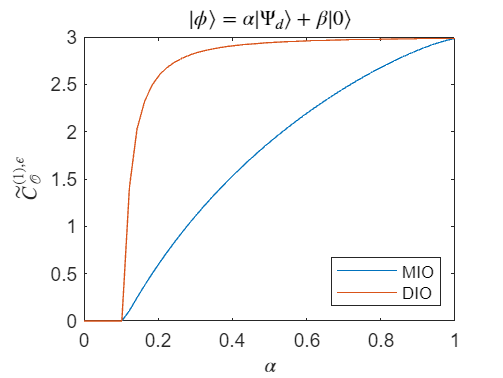


plot(arr_a, log2(arr_mio));
hold on
plot(arr_a, log2(arr_dio));
hold off

lgd = legend("MIO", "DIO");
lgd.Location = 'southeast';

txt = xlabel("$\alpha$");
set(txt, 'Interpreter', 'latex');

txt = title("$|\phi\rangle = \alpha |\Psi_d\rangle + \beta |0\rangle$");
set(txt, 'Interpreter', 'latex');

% txt = ylabel("One-shot Coherence Dilution");
txt = ylabel("$\tilde{C}_{\mathcal{O}}^{(1), \epsilon}$");
set(txt, "Interpreter", 'latex');

% save fig
filename = sprintf('test1_%d.pdf', n);
print(fig, filename, '-dpdf');

% test2

d = 8

d = 8

tols = [0.1 0.01 0.001]

tols =     0.1000    0.0100    0.0010



psi = ones(d, 1) / sqrt(d);

z = zeros(d, 1);
z(1) = 1;

c = psi' * z

c = 0.3536


n = 50;
arr_a = linspace(0, 1, n);
arr_b = zeros(1, n);
arr_mio = zeros(n, length(tols));
arr_dio = zeros(n, length(tols));

for i = 1:length(arr_a)
    disp(i);
    a = arr_a(i);
    b1 = -a * c + sqrt(a * a * (c * c - 1) + 1);
    % b2 = -a * c - sqrt(a * a * (c * c - 1) + 1);

    arr_b(i) = b1;

    phi = a * psi + b1 * z;
    % disp(a);
    % disp(b1);
    % disp(b2);
    % disp(phi);
    % disp(norm(phi));
    assert(abs(norm(phi) - 1.0) < 1e-7);

    for j = 1:length(tols)
        tol = tols(j);

        c_mio = coherence_dilution_oneshot_pure_MIO(phi, tol);
        arr_mio(i,j) = c_mio;
    
        c_dio = coherence_dilution_oneshot_pure_DIO_bisection(phi, tol, 1e-2);
        arr_dio(i,j) = c_dio;
    end
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50




% save data
filename = sprintf("test2_%d.mat", n)

filename = "test2_50.mat"

save(filename, 'd', 'tols', 'arr_a', 'arr_b', 'arr_mio', 'arr_dio');

% test2 plot

% load data
n = 50;
filename = sprintf("test2_%d.mat", n)

filename = "test2_50.mat"

load(filename);

% plot
fig = figure

fig =   Figure (15) - 属性:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 338 560 420]
       Units: 'pixels'

  显示 所有属性


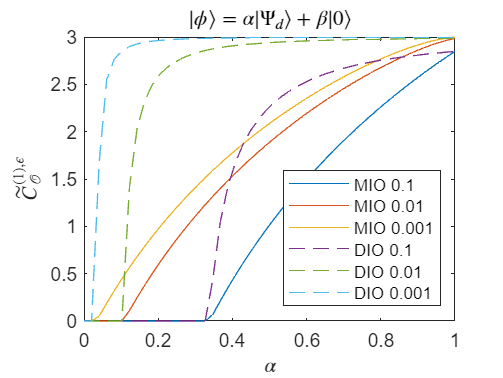


plot(arr_a, log2(arr_mio(:, 1)));
hold on
plot(arr_a, log2(arr_mio(:, 2)));
hold on
plot(arr_a, log2(arr_mio(:, 3)));
hold on

plot(arr_a, log2(arr_dio(:, 1)), "--");
hold on
plot(arr_a, log2(arr_dio(:, 2)), "--");
hold on
plot(arr_a, log2(arr_dio(:, 3)), "--");

hold off

lgd = legend( ...
    "MIO 0.1", ...
    "MIO 0.01", ...
    "MIO 0.001", ...
    "DIO 0.1", ...
    "DIO 0.01", ...
    "DIO 0.001" ...
);
lgd.Location = 'southeast';

txt = xlabel("$\alpha$");
set(txt, 'Interpreter', 'latex');

txt = title("$|\phi\rangle = \alpha |\Psi_d\rangle + \beta |0\rangle$");
set(txt, 'Interpreter', 'latex');

% txt = ylabel("One-shot Coherence Dilution");
txt = ylabel("$\tilde{C}_{\mathcal{O}}^{(1), \epsilon}$");
set(txt, "Interpreter", 'latex');

% save
filename = sprintf("test2_%d.pdf", n);
print(fig, filename, '-dpdf');


$$\begin{array}{l}
C_{\max }^{\epsilon } \left(\rho \right)\;{\le C}_{\textrm{MIO}}^{\epsilon } \left(\rho \right)\le C_{\max }^{\epsilon } \left(\rho \right)+1\\
C_{\max ,\Delta }^{\epsilon } \left(\rho \right)\le C_{\textrm{DIO}}^{\epsilon } \left(\rho \right)\le C_{\max ,\Delta }^{\epsilon } \left(\rho \right)+1\\
{\left∣\phi \right\rangle}=\alpha {\left∣\Psi_m \right\rangle}+\beta {\left∣0\right\rangle}
\end{array}$$


% test3

d = 8

d = 8

tol = 0.01

tol = 0.0100


psi = ones(d, 1) / sqrt(d);

z = zeros(d, 1);
z(1) = 1;

c = psi' * z

c = 0.3536


n = 20;
arr_a = linspace(0, 1, n);
arr_b = zeros(1, n);
arr_mio = zeros(1, n);
arr_dio = zeros(1, n);

arr_ecmax = zeros(1, n);
arr_ecmaxd = zeros(1, n);

for i = 1:length(arr_a)
    disp(i);
    a = arr_a(i);
    b1 = -a * c + sqrt(a * a * (c * c - 1) + 1);
    % b2 = -a * c - sqrt(a * a * (c * c - 1) + 1);

    arr_b(i) = b1;

    phi = a * psi + b1 * z;
    % disp(a);
    % disp(b1);
    % disp(b2);
    % disp(phi);
    % disp(norm(phi));
    assert(abs(norm(phi) - 1.0) < 1e-7);
    
    c_mio = coherence_dilution_oneshot_pure_MIO(phi, tol);
    arr_mio(i) = c_mio;

    c_dio = coherence_dilution_oneshot_pure_DIO_bisection(phi, tol, 1e-2);
    arr_dio(i) = c_dio;

    e_c_max = smoothed_coherence_max_relative_entropy_pure(phi, tol);
    e_c_max_d = smoothed_coherence_max_delta_relative_entropy_pure_bisection(phi, tol, 1e-4);

    arr_ecmax(i) = e_c_max;
    arr_ecmaxd(i)= e_c_max_d;
end

     1



     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20



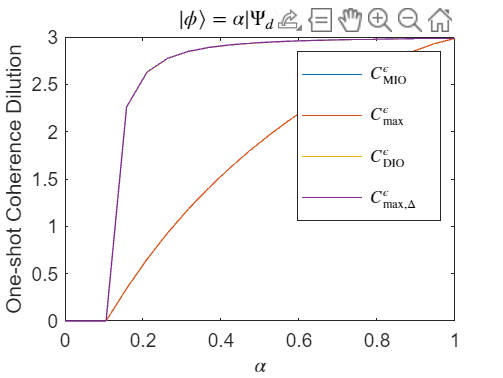

% test3 plot

figure

plot(arr_a, log2(arr_mio));
hold on
plot(arr_a, arr_ecmax);
hold on

plot(arr_a, log2(arr_dio));
hold on
plot(arr_a, arr_ecmaxd);
hold off

legend("$C_{\mathrm{MIO}}^\epsilon$", "$C_{\max}^\epsilon$", "$C_{\mathrm{DIO}}^\epsilon$", "$C_{\max, \Delta}^\epsilon$", 'Interpreter', 'latex');
txt = xlabel("$\alpha$");
set(txt, 'Interpreter', 'latex');
txt = title("$|\phi\rangle = \alpha |\Psi_d\rangle + \beta |0\rangle$");
set(txt, 'Interpreter', 'latex');
ylabel("One-shot Coherence Dilution");